# Linear Regression:

The data in the accompanying table relate heart rate at rest Y to kilograms body weight X.

clear all
X = [90, 86, 67, 89, 81, 75]

X =     90    86    67    89    81    75


Y = [62, 45, 40, 55, 64, 53]

Y =     62    45    40    55    64    53


## Q: Graph these data. Does it appear that there is a linear relationship between body weight and heart rate at rest?

A:

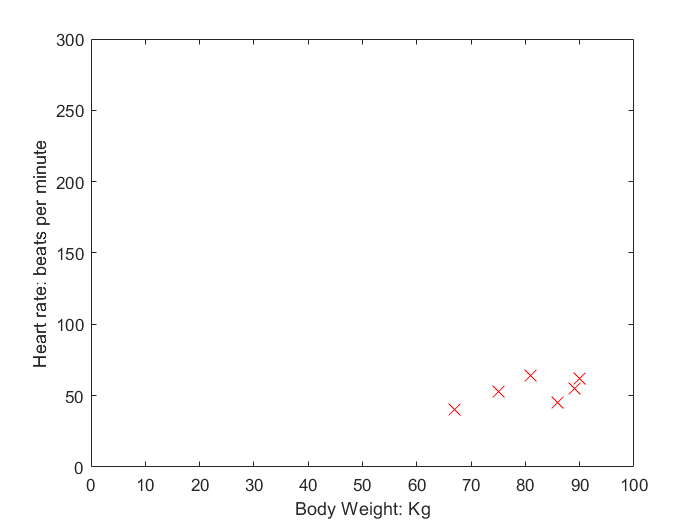

plot_data(X,Y)

Yes, a direct linear relationship.

## Q: Compute a,b and write the regression equation for these data. Plot the regression line on the graph. Interpret the estimated regression coefficients.

A:

close all
Theta = normal_equation(X,Y)

Theta =     4.7990
    0.5947


points = linspace(min(X)-30,max(X)+30,10);

line = predict(points, Theta);

J = cost_function(X, Y', Theta); %% error

J = 2.5461e-25

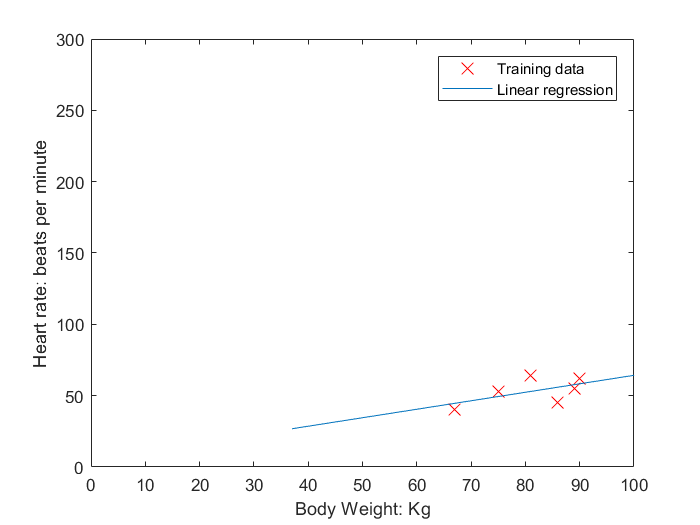


plot_data(X, Y);hold on
plot(points,line, '-');hold off
legend('Training data', 'Linear regression')

 Theta $\theta=(4.799; 0.5947)$ are the coeficients of the Hypotesis $h(x,\theta) = \theta_0 * x_0 + \theta_1 * x_1$ being $x_0$ the bias term = 1. This hypotesis represent a linear equation so $\theta_0$ is the point where the line cuts the y axis. $\theta_1$ is a factor that represents how important is the feature X.

## Q: Now examine the data point(67, 40). If this data point were removed from the data set, what changes would occur in the estimates of a and b $(\theta)$?

A:

clear all;

newX = [90, 86, 89, 81, 75]

newX =     90    86    89    81    75


newY = [62, 45, 55, 64, 53]

newY =     62    45    55    64    53



Theta = normal_equation(newX, newY)

Theta =    49.1641
    0.0788


The point is the min value of the function, so the $\theta$ changes a lot. The line has de capacity of change the slope adapting better to the new form of the data, in this case decreasing the slope, so $\theta_0$ has a higher value and $\theta_1$ as a lower value.